FJ11 = csvread('FJ11.csv');
FJ3 = csvread('FJ3.csv');
load('ZZZ.mat');
R = 300.4;
ddF = 0.2913;
for e=1:length(ddF)
    F=0.466*R+ddF(e);    
    dF=0.316;
    w=10000000000;    
    for i=1:length(dF)
        f=dF(i)+F;%抛物面顶点到焦点的距离
        c=-4*f*(R+dF(i));
        n=1;
        for j=1:length(FJ11)
            r2(j,1)=sqrt( (FJ11(j,1) + 49.3194 )^2+( FJ11(j,2) + 36.889 )^2 + ( FJ11(j,3) + 294.019) ^2 );
            %到顶点的距离要小于155.5806，这个是用余弦定理算出来的
            if r2(j,1)<=155.5806
                FJ111(n,1)=FJ11(j,1);
                FJ111(n,2)=FJ11(j,2);
                FJ111(n,3)=FJ11(j,3);
                FJ111(n,4)=FJ11(j,4);
                FJ111(n,5)=sqrt( (FJ111(n,1) + 49.3194) ^2 + (FJ111(n,2) + 36.889) ^2 + (FJ111(n,3) + 294.019)^2);
                n=n+1;
            end
        end
        ZZ = FJ111(:,5);
    
        tem = ppval(ZZZ,ZZ);%已知的样条插值函数和自变量点,计算出样条插值函数在该点的值
        tem(132) = 300.716;%问题一得到的最佳半径
        for k=1:length(FJ111)
            rl(k,1)=sqrt((FJ111(k,1))^2+(FJ111(k,2))^2+(FJ111(k,3))^2);
            sital(k,1)=acos(FJ111(k,3)/rl(k));
            fail(k,1)=atan(FJ111(k,2)/FJ111(k,1));
            
            %通过计算得到的最优半径
            rl(k,2)=tem(k);
            
            rl(k,3)=rl(k,1)-rl(k,2);
            
            %新的xyz
            rl(k,4)=rl(k,2)*sin(sital(k,1))*cos(fail(k,1));
            rl(1,4)=0;
            rl(k,5)=rl(k,2)*sin(sital(k,1))*sin(fail(k,1));
            rl(1,5)=0;
            rl(k,6)=rl(k,2)*cos(sital(k,1));
        end
        r(:,1)=rl(:,3);
        % W 主索节点最大径向调节量
        W(i)=max(max(abs(r)));
        %判断附件3中4300块反射板每一个主索节点是否符合300m要求
        for l=1:3
            for m=1:4300
                %ismember 判断FJ3中哪些元素存在于FJ111，存在返回1
                %比如m=1，就是FJ3（1，1）这个元素是否在FJ111第四列中
                x(m)=ismember(FJ3(m,l),FJ111(:,4));
                %FJ4就是将FJ3不在FJ111上的点变为0
                if x(m)>0
                    FJ4(m,l)=FJ3(m,l);
                else
                    FJ4(m,l)=0;
                end
            end
        end

        tz1(:,1:3)=FJ111(:,1:3);%原xyz
        tz2(:,1:3)=rl(:,4:6);%加dF后的xyz
        tz1=tz1./abs(tz1);

        tz1(isnan(tz1))=1;%将所有nan替换成1
        tz2=abs(tz2).*tz1;%有点像平方

        rl(:,4:6)=tz2(:,1:3);
        for M=1:length(FJ4)
            if FJ4(M,1)>5 && FJ4(M,2)>5 && FJ4(M,3)>5
                %比如M=1，A A1 A2是一块反射板的三个主索节点在FJ111表格的位置
                %然后求这三个点之间的距离，以及变化后的距离
                %返回的是该点在FJ111矩阵中的位置
                [A,B]=find(FJ111(:,4)==FJ4(M,1));
                [A1,B1]=find(FJ111(:,4)==FJ4(M,2));
                [A2,B2]=find(FJ111(:,4)==FJ4(M,3));
                
                %这是求原本两个点之间的距离分别是1和2 1和3 2和3
                len(M,1)=sqrt((FJ111(A,1)-FJ111(A1,1))^2+(FJ111(A,2)-FJ111(A1,2))^2+(FJ111(A,3)-FJ111(A1,3))^2);
                len(M,2)=sqrt((FJ111(A,1)-FJ111(A2,1))^2+(FJ111(A,2)-FJ111(A2,2))^2+(FJ111(A,3)-FJ111(A2,3))^2);
                len(M,3)=sqrt((FJ111(A1,1)-FJ111(A2,1))^2+(FJ111(A1,2)-FJ111(A2,2))^2+(FJ111(A1,3)-FJ111(A2,3))^2);

                %这是求变化后两点间的距离
                len1(M,1)=sqrt((rl(A,4)-rl(A1,4))^2+(rl(A,5)-rl(A1,5))^2+(rl(A,6)-rl(A1,6))^2);
                len1(M,2)=sqrt((rl(A,4)-rl(A2,4))^2+(rl(A,5)-rl(A2,5))^2+(rl(A,6)-rl(A2,6))^2);
                len1(M,3)=sqrt((rl(A1,4)-rl(A2,4))^2+(rl(A1,5)-rl(A2,5))^2+(rl(A,6)-rl(A2,6))^2);

                %求lamda
                det(M,1)=abs(len1(M,1)-len(M,1))/len(M,1);
                det(M,2)=abs(len1(M,2)-len(M,2))/len(M,2);
                det(M,3)=abs(len1(M,3)-len(M,3))/len(M,3);

            end
        end
        dete(i)=min(max(det));%一次max是找列向量的最大值，两次是全部的
        lv(i)=abs(sum(len)-sum(len1))/sum(len);
        if dete(i)<=w
            w=dete(i);
            cc=W(i);
            o=dF(i)+R;
            ol=rl;
            oo=0.534*R-ddF(e);
            ooo=det;
            oooo=lv(i);               
            di=tz2;
        end
        
    end
end
aa=1-sum(sum(ooo>0.0007))/numel(ooo);

disp('理想抛物面顶点距离原点长度为：')

理想抛物面顶点距离原点长度为：


disp(o)

  300.7160



disp('焦点距离原点长度为：')

焦点距离原点长度为：


disp(oo)

  160.1223



disp('促动器最大伸缩量为：')

促动器最大伸缩量为：


disp(cc)

    0.3824



disp('将基础球面调节至理想抛物面节点间距离最大变化幅度：')

将基础球面调节至理想抛物面节点间距离最大变化幅度：


disp(w)

    0.0012



disp('所有节点间距离整体变化幅度：')

所有节点间距离整体变化幅度：


disp(oooo)

    0.0069



disp('节点间距离变化幅度合格率：')

节点间距离变化幅度合格率：


disp(aa)

    0.6731



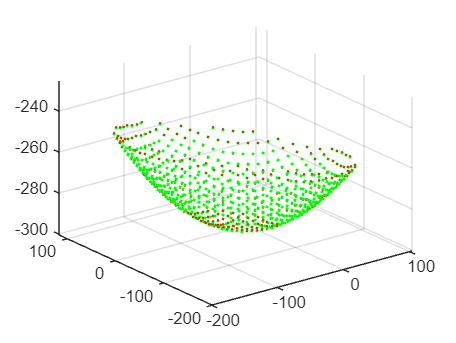


x3=di(:,1);
y3=di(:,2);
z3=di(:,3);
scatter3(x3,y3,z3,3,'*','g')
hold on
x1=FJ111(:,1);
y1=FJ111(:,2);
z1=FJ111(:,3);
scatter3(x1,y1,z1,15,'.','r')

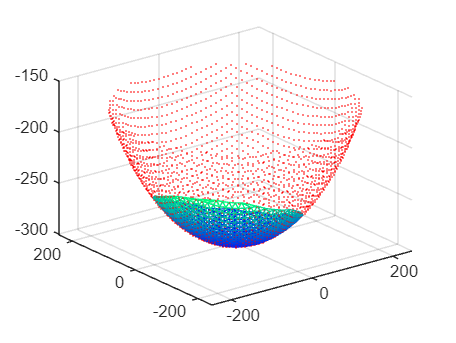


figure
x1=FJ111(:,1);
y1=FJ111(:,2);
z1=FJ111(:,3);
tr1=delaunay(x1,y1);
trimesh(tr1,x1,y1,z1);
colormap winter
hidden off
hold on
x=FJ11(:,1);
y=FJ11(:,2);
z=FJ11(:,3);
scatter3(x,y,z,1,'*','r')